4.2.1 Setup

clear;

s = tf('s');

g = 9.8;
M = 1; %kg
R = 3; %Ohm
L = 1; %H

y0 = 1;
i0 = sqrt(M*g*y0^2);
u0 = i0*R;

A = [0, 1, 0;
    2*g/y0, 0, (-2/y0)*sqrt(g/M);
    0, 0, -R/L];

b = [0; 0; 1/L];

c = [1; 0; 0];

d = 0;

4.2.1/4.2.2 Stability

eig(A)

ans =     4.4272
   -4.4272
   -3.0000


sys = ss(A, b, c', d);

% One is positive, the system is unstable

The system's stability is largely governed by the magnetic force acting on the steel ball, which is inversely proportional to the square of the distance between the ball and the electromagnet (as given by the force equation F = i^2/R^2). When the ball moves closer to the electromagnet, the magnetic force increases at a rate faster than the distance decreases (because of the square term in the denominator). Similarly, when the ball moves away, the force decreases more rapidly.

4.2.2 Transfer Function From Linear and From MATLAB Methods (Pg. 5 Mid)

% Display the transfer function of the Linearized Sys
[num, den] = ss2tf(A, b, c', d);
sys_tf = tf(num, den);
sys_tf 

sys_tf =
 
            -6.261
  ---------------------------
  s^3 + 3 s^2 - 19.6 s - 58.8
 
Continuous-time transfer function.
Model Properties



% Display the computed tf from the nonlinear system
K = -2*i0/(M*y0^2*L);
denom = (s+R/L)*(s^2 - 2*i0^2/M/y0^3);
G = K/denom

G =
 
            -6.261
  ---------------------------
  s^3 + 3 s^2 - 19.6 s - 58.8
 
Continuous-time transfer function.
Model Properties



% Identical Terms
% No zero three poles
zero(G)


ans =

  0×1 empty double column vector



pole(G)

ans =     4.4272
   -4.4272
   -3.0000


4.2.3/4.2.4 Linearizing System in Matlab (with linmod)

[sizes, x0, states] = magball

sizes =      3
     0
     1
     1
     0
     1
     1


x0 =     1.0000
         0
    3.1305


states = 3×1 cell array
    {'magball/Magnetic Ball-suspension System/y'    }
    {'magball/Magnetic Ball-suspension System/y_dot'}
    {'magball/Magnetic Ball-suspension System/i'    }


[A1, B1, C1, D1] = linmod('magball', x0, u0)

A1 =          0    1.0000         0
   19.6000         0   -6.2610
         0         0   -3.0000


B1 =          0
         0
    1.0000


C1 =      1     0     0


D1 = 0

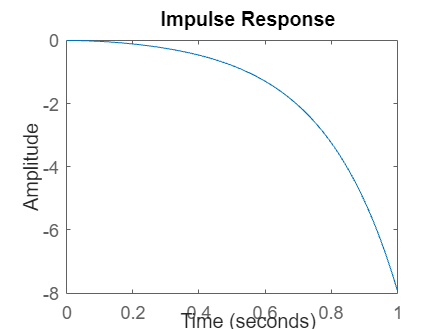

sys_w_linmod = ss(A1, B1, C1, D1);
impulse(sys_w_linmod, [0, 1])




%%%% Recall From Preperation %%%%
syms ss;

g = 9.8;
M = 1; % kg
R = 3; % Ohm
L = 1; % H

y0 = 1;
i0 = sqrt(M*g*y0^2);

K = -2*i0/(M*y0^2*L);
denom = (ss+R/L)*(ss^2 - 2*i0^2/(M*y0^3));
G_s = K/denom;

% Inverse Laplace Transform
g_t = ilaplace(G_s)

$$g\_t = \frac{15\,\sqrt{2}\,\sinh\left(\frac{7\,\sqrt{2}\,\sqrt{5}\,t}{5}\right)}{53}-\frac{14\,\sqrt{5}\,\cosh\left(\frac{7\,\sqrt{2}\,\sqrt{5}\,t}{5}\right)}{53}+\frac{14\,\sqrt{5}\,{\mathrm{e}}^{-3\,t}}{53}$$

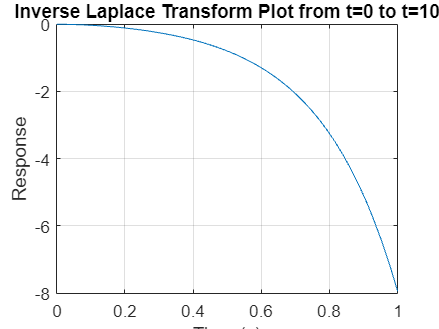


fplot(g_t, [0, 1]);
xlabel('Time (s)');
ylabel('Response');
title('Inverse Laplace Transform Plot from t=0 to t=10');
grid on;



% Identical

4.2.5 a) Step Response w/ step()

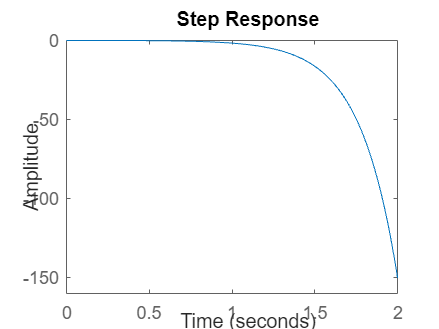

step(sys_w_linmod, [0 2]) % Initial Condition is vector zero

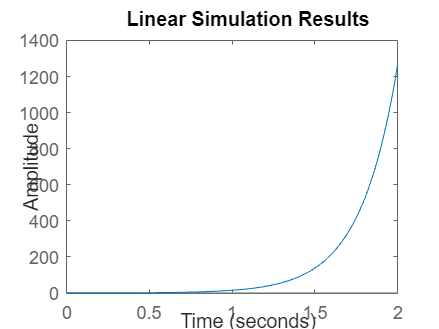


tt = linspace(0, 2, 1000);
lsim(sys_w_linmod, ones(size(tt)), tt, [y0; 0; i0]); % With Initial Condition

4.2.5 b) Step Response w/ Simulink

- Initial condition is zero:

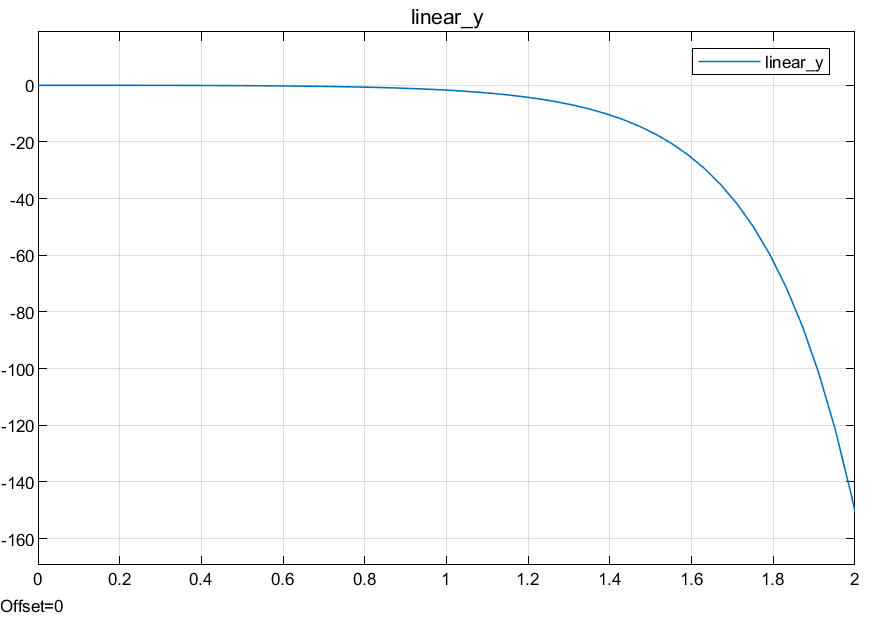

          2. Initial condition is [y0; 0; i0]: